clc
clear all
close all

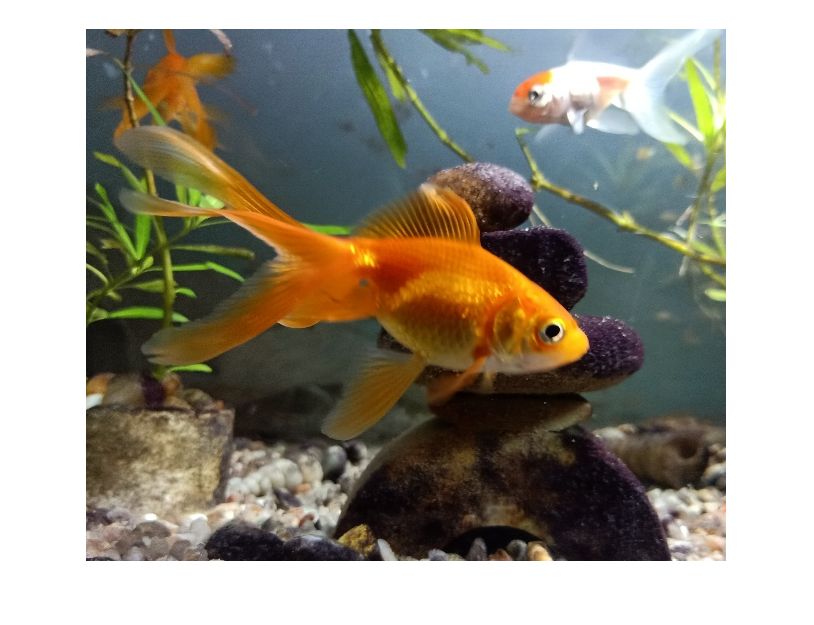

I = imread('C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-3.jpg');
figure; imshow(I);

load('rcnnStopSigns.mat','layers');

sample1 = {'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-1.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-2.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Fish-1.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-4.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-5.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-6.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-7.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-8.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-9.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-10.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-11.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-12.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-13.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-14.jpg';
           'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics\Fish_Image\Goldfish-15.jpg';};
sample2 = {[12.5,7.5,242,171];
           [60.5,84.5,852,519];
           [33.2321428571429,54.4642857142857,659.678571428571,322.285714285714];
           [10.5,34.5,225,108];
           [190.5,134.5,864,927];
           [282.5,78.5,747,780];
           [43.5,9.5,217,147];
           [13,27,171,115];
           [32.5,24.5,216,149];
           [11.5,9.5,584,488];
           [89 ,7 ,184 ,137];
           [240.5 ,98.5 ,328 ,210];
           [192.5 ,143.5 ,622 ,524];
           [54.5 ,22.5 ,253 ,177];
           [322.5 ,234.5 ,465 ,328]};
label = table(sample1,sample2);

imdir=fullfile('C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics')

imdir = 'C:\Users\FishWade\Desktop\Matlab Codes\Data Science Information\Image_Video_Analytics'

options = trainingOptions('sgdm','MiniBatchSize', 32, 'InitialLearnRate', 1e-6, 'MaxEpochs', 20)

options =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-06
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 20
               MiniBatchSize: 32
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: []
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'none'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirection: 'right'
        Dispatc

train = trainRCNNObjectDetector(label,layers,options,'NegativeOverlapRange',[0 0.3]);

*******************************************************************
Training an R-CNN Object Detector for the following object classes:

* sample2

--> Extracting region proposals from 15 training images...done.

--> Training a neural network to classify objects in training data...



Error using trainNetwork (line 183)
The class names of layer 15 must match the class names of the training data. The training data class names are given by categories(Y), where Y are the training data labels.

Error in rcnnObjectDetector.train (line 234)
            [net, info] = trainNetwork(dispatcher, layers, opts);

Error in 